# Chapter 08: Dimension Reduction

close all; clear all;

## Principal component analysis (PCA)

The k-dimensional linear subspace $\mathcal{W}$ of $\mathbb{R}^d$ that minimizes 


$$\sum_{i=1}^{m} \mathrm{dist}_{\ell_2}(x^{(i)},\mathcal{W})^2$$


is spanned by the first $k$ left singular vectors of the data matrix $X$, where the $i$th column of the data matrix $X$ is $x^{(i)}$. 

One uses both the built-in svd command and the eigendecomposition method to compute the first $k
$ left singular vectors of $X$ and compare the computation times.

% generate high-dimensional data for principal component analysis
d = 1000;             % original dimension
m = 500;              % number of datapoints
k = 100;              % reduced dimension
X = rand(d,m);        % generate random datapoints

% compute the first k left singular vectors of X via the built-in svd command 
% and record the computation time
tic;
[U_svd,~,~] = svd(X);
time_svd = toc;
U_svd = U_svd(:,1:k);
fprintf('The computation time for the built-in svd command is %.8f seconds',time_svd)

The computation time for the built-in svd command is 0.06896836 seconds

% compute the first k left singular vectors of X via the eigendecomposition of X^T*X 
% and count the computation time
tic;
[V,D] = eig(X'*X,'vector');
% compute left singular vectors of X
time_eig = toc;
U_eig = X * V(:,m-k+1:end) *  diag(1./sqrt(D(m-k+1:end,:)));
U_eig = flip(U_eig,2);
fprintf('The computation time for eigendecomposition method is %.8f seconds',time_eig)

The computation time for eigendecomposition method is 0.01956504 seconds

## Johnson-Lindenstrauss lemma

close all; clear all;
% generate high-dimensional data for the Johnson-Lindenstrauss lemma
d = 100000;                          % original dimension
m = 1000;                            % number of datapoints
X = rand(d,m);                       % generate random datapoints
delta = 1/5;
k = ceil(18*log(m) / (delta^2))    % reduced dimension

k = 3109

A = randn(k,d) / sqrt(k);            % the matrix used in the Johnson-Lindenstrauss lemma

Below, one computes the 3 exact nearest neighbors and 3 JL-based approximate nearest neighbors of the first datapoint. The indices of nearest neighbors and the distances to the nearest neighbors are returned. One also compares computation times.

A function performing a "brute force" nearest neighbor search is defined at the end of the document.

n = 3;
tic;
[index_ex,dist_ex] = nn_brute_force(X(:,1),X(:,2:end),n);
stop_ex = toc;
fprintf(['Three exact nearest neighbors found at indices %d,%d,%d ' ...
    'with distances %.4f,%.4f,%.4f in %.8f seconds.'],1+index_ex,dist_ex,stop_ex)

Three exact nearest neighbors found at indices 429,465,286 with distances 128.2506,128.2727,128.2855 in 0.90641641 seconds.

X_JL = A*X;
tic;
[index_JL,~] = nn_brute_force(X_JL(:,1),X_JL(:,2:end),n);
stop_JL = toc;
dist_JL = [norm(X_JL(:,1)-X_JL(:,index_JL(1))), norm(X_JL(:,1)-X_JL(:,index_JL(2))), ...
           norm(X_JL(:,1)-X_JL(:,index_JL(3))) ];
fprintf(['Three approximate nearest neighbors found at indices %d,%d,%d ' ...
    'with distances %.4f,%.4f,%.4f in %.8f seconds.'],1+index_JL,dist_JL,stop_JL)

Three approximate nearest neighbors found at indices 192,382,333 with distances 129.5257,127.4675,128.7886 in 0.03537232 seconds.

## Locally linear lmbedding (LLE)

A function implementing the LLE procedure is defined at the end of the document.

### Example 1: Swiss-Roll

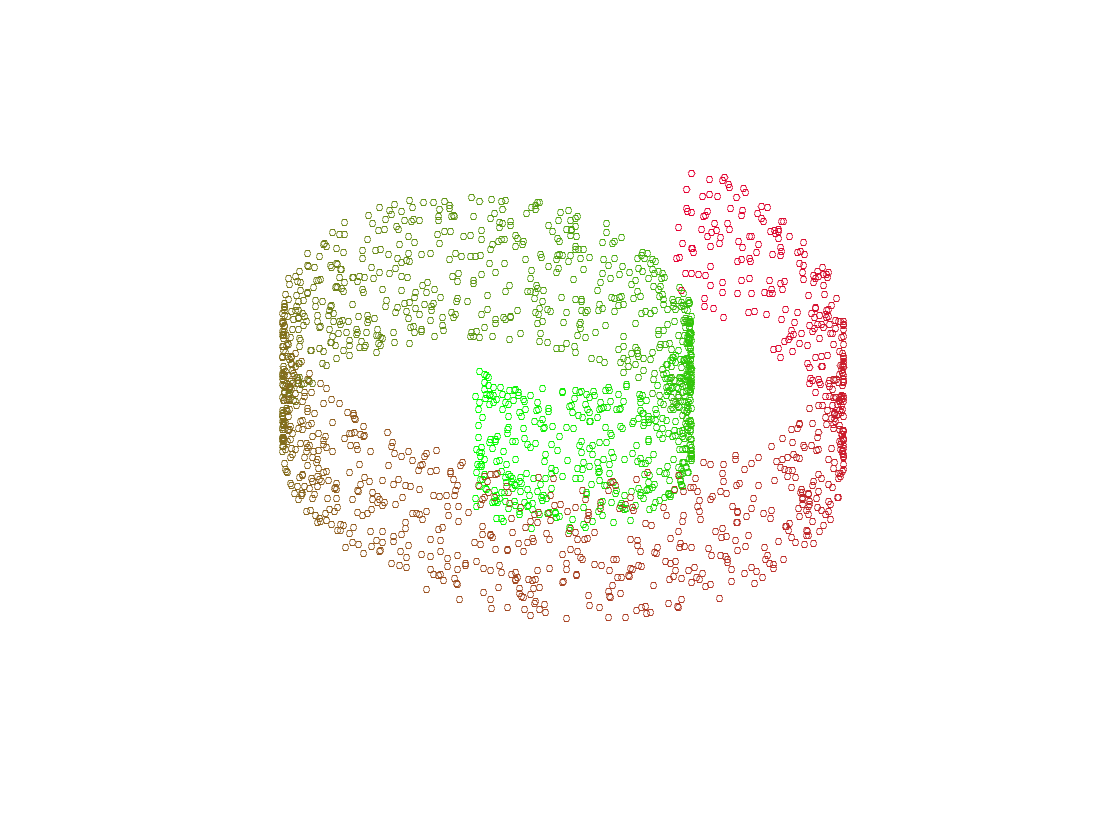

close all; clear all;
% generate datapoints along a nonlinear manifold
m = 2000;
t = (3*pi/2)*(1+2*rand(m,1));  
height = 21*rand(m,1);
X = [t.*cos(t), t.*sin(t), height];
% visualize the datapoints
pix = (t-min(t))/(max(t)-min(t));
color = [0.9*pix, 1-pix, 0.2*pix];
scatter3(X(:,1),X(:,2),X(:,3),12,color,'o');
set(gca,'XTick',[],'Xcolor','none')
set(gca,'YTick',[],'Ycolor','none')
set(gca,'ZTick',[],'Zcolor','none')
view([30 70])

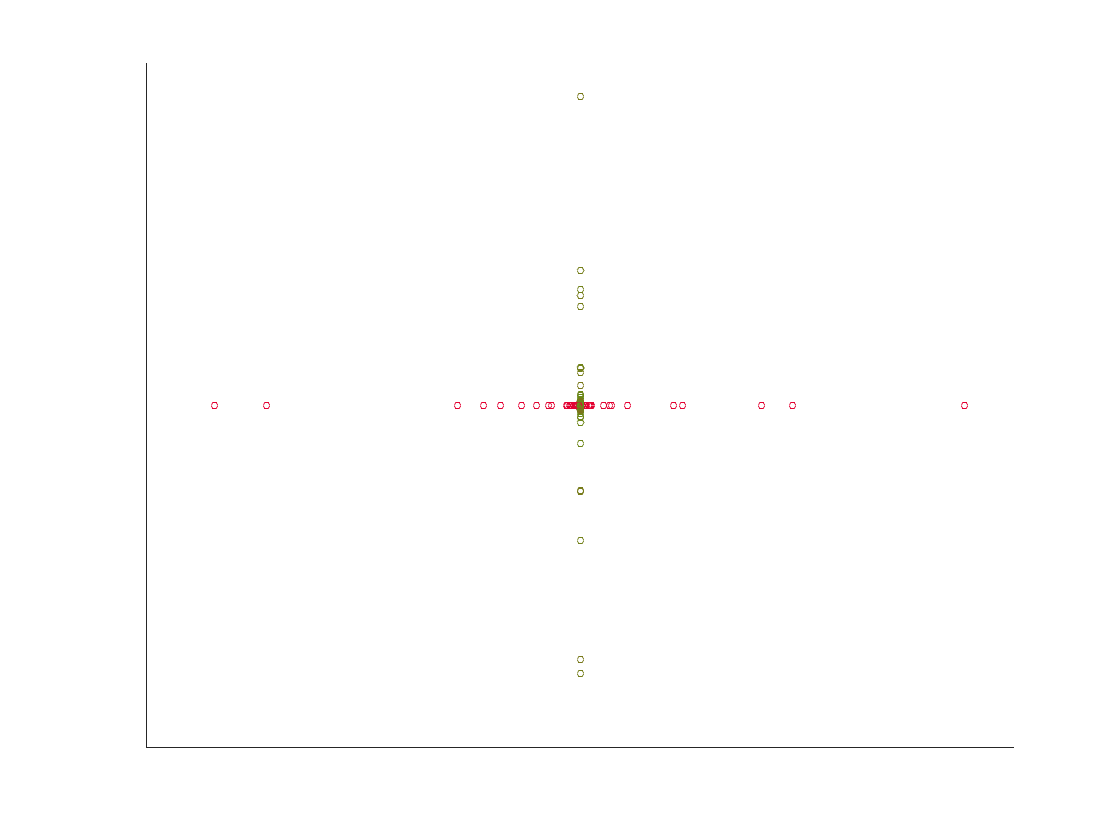

% perform LLE for the given dataset and plot the output
n = 10;                   % number of nearest neighbors       
k = 2;                              % reduced dimension       
Z = lle(X,n,k);
scatter(Z(:,1),Z(:,2),12,color,'o')
set(gca,'XTick',[])
set(gca,'YTick',[])

## Example 2: datapoints along the axes

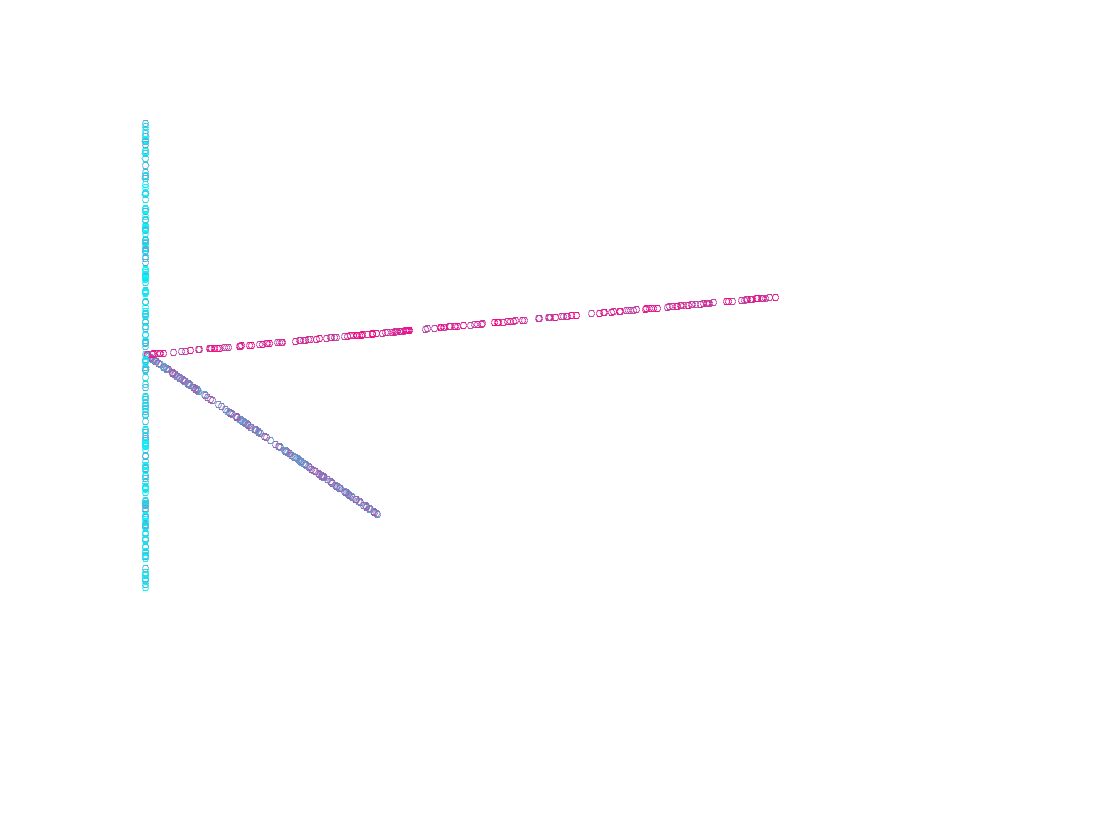

% generate the datapoints in xyz axes
m = 600;     % m has to be a multiple of 3
X = [rand(m/3,1),zeros(m/3,1),zeros(m/3,1);...
    zeros(m/3,1),rand(m/3,1),zeros(m/3,1);...
    zeros(m/3,1),zeros(m/3,1),2*rand(m/3,1)-1];
% visualize the datapoints
pix = linspace(0,1,m)';
color = [1-pix, pix, (1+pix)/2];
scatter3(X(:,1),X(:,2),X(:,3),12,color,'o');
set(gca,'XTick',[],'Xcolor','none')
set(gca,'YTick',[],'Ycolor','none')
set(gca,'ZTick',[],'Zcolor','none')
view([20 -20])

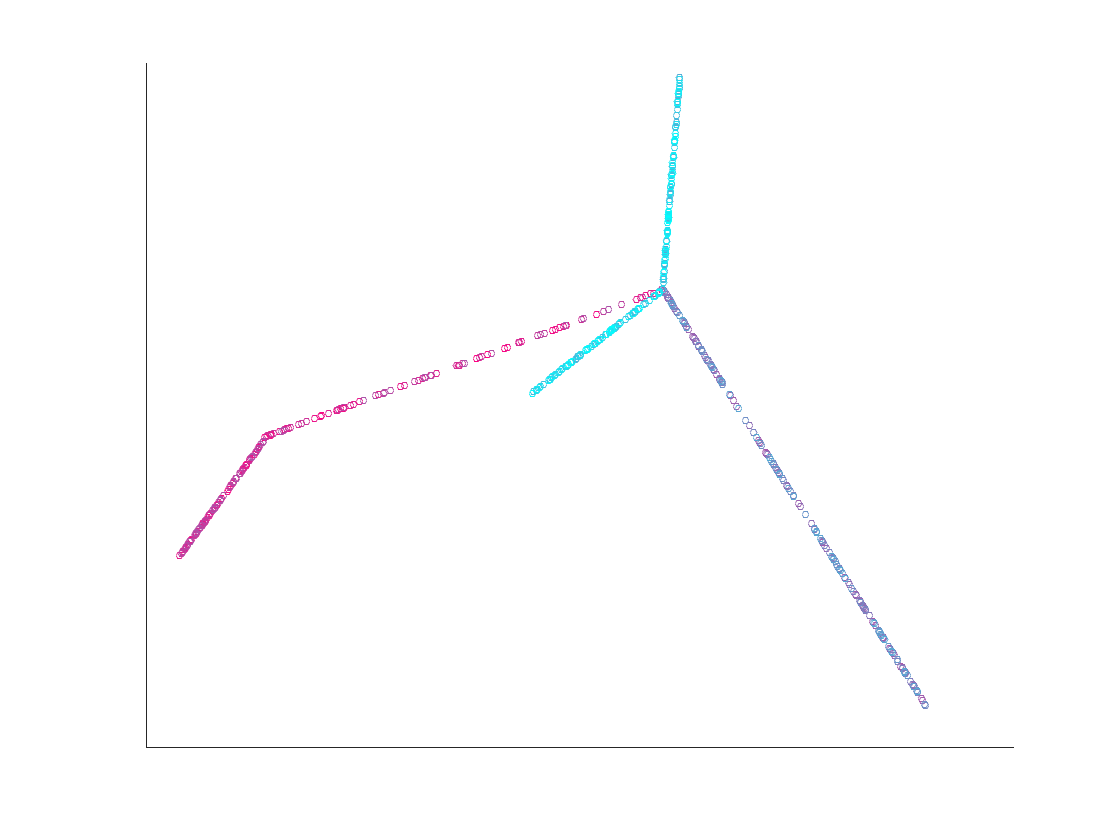

% perform LLE for the given dataset and plot the output
n = 10;                   % number of nearest neighbors
k = 2;                              % reduced dimension 
Z = lle(X,n,k);
scatter(Z(:,1),Z(:,2),12,color,'o')
set(gca,'XTick',[])
set(gca,'YTick',[])

The functions defined below both use the built-in function pdist2 producing all the pairwise distances between two datasets.

- nn_brute-forcs computes the n nearest neighbors to a point x among among a set of datapoints (represented by the columns of X) --- it returns the indices of the neighbors and the corresponding distances to x;

- lle perfoms the locally linear embedding procedure on the dataset X using n nearest neighbors to produce points in dimension k.

function [idx,dist] = nn_brute_force(x,X,n) 
distances = pdist2(x',X');
[dist,idx] = mink(distances,n);
end

% Here is a function implementating Locally Linear Embedding
function Z = lle(X,k,d)
[n,p] = size(X);
%% Step 1: Find k-nearest neighbors for each data
D = pdist2(X,X);            % pairwise distance matrix
[~,index] = sort(D);
idx = index(2:k+1,:);       % index of k-nearest neighbors for each data
%% Step 2: Compute weights
if (k>d)
tol=1e-3; % regularlizer in case constrained fits are ill conditioned
else
  tol=0;
end
W = zeros(n,n);   
for i=1:n
    M = X(idx(:,i),:) - X(i,:);
    G = M*M';
    G = G + eye(k,k)*tol*trace(G);
    Ginv = inv(G);
    w = 1/sum(sum(Ginv))*Ginv*ones(k,1);
    W(idx(:,i),i) = w;
end
%% Step 3: Find low-dimensional representation
[V,D] = eig((eye(n)-W)*(eye(n)-W)');
Z = V(:,2:d+1);
end  